% Generar una señal
fs = 1000; % Frecuencia de muestreo
t = 0:1/fs:1; % Vector de tiempo
signal = sin(2*pi*50*t) + 0.5*sin(2*pi*120*t) + randn(size(t)); % Señal con ruido

% Leer el archivo de audio
[signal, fs] = audioread('music2.wav');
% Vector de tiempo
t = (0:length(signal)-1)/fs;

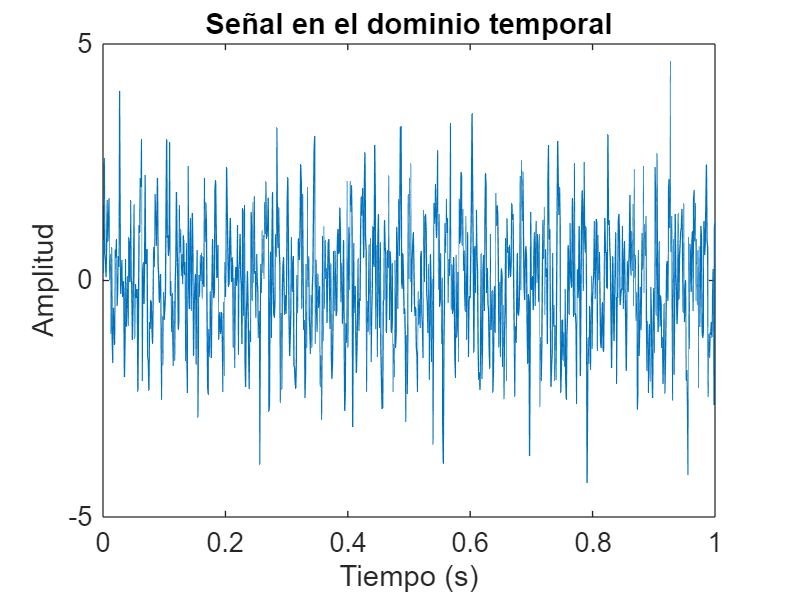

% Mostrar señal
figure;
plot(t, signal);
title('Señal en el dominio temporal');
xlabel('Tiempo (s)');
ylabel('Amplitud');

% Transformada de Fourier
n = length(signal);
f = (0:n-1)*(fs/n); % Vector de frecuencia
X = abs(fft(signal)); % Magnitud del espectro
X = X(1:floor(n/2)); % Usar solo la mitad del espectro
f = f(1:floor(n/2)); % Ajustar vector de frecuencia

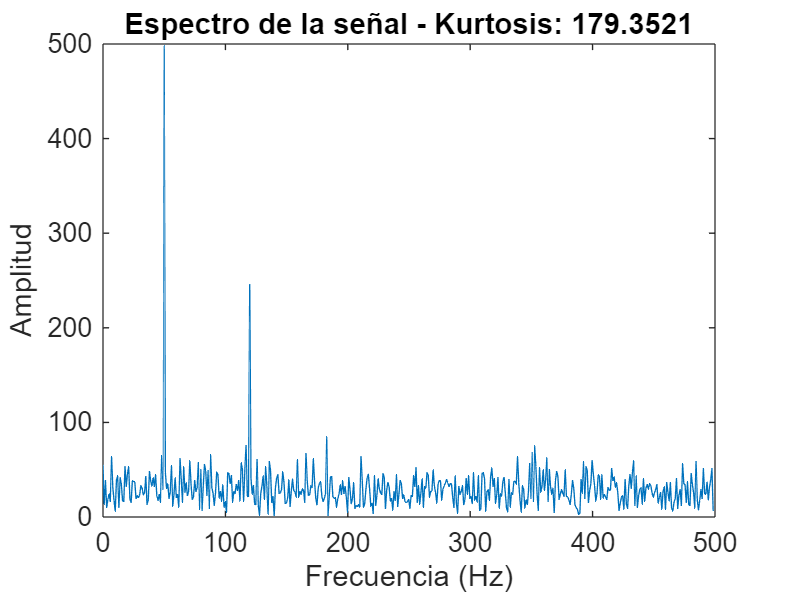

% Calcular Kurtosis espectral
kurt_val = kurtosis(X);

% Mostrar espectro y kurtosis
figure;
plot(f, X);
title(['Espectro de la señal - Kurtosis: ', num2str(kurt_val)]);
xlabel('Frecuencia (Hz)');
ylabel('Amplitud');

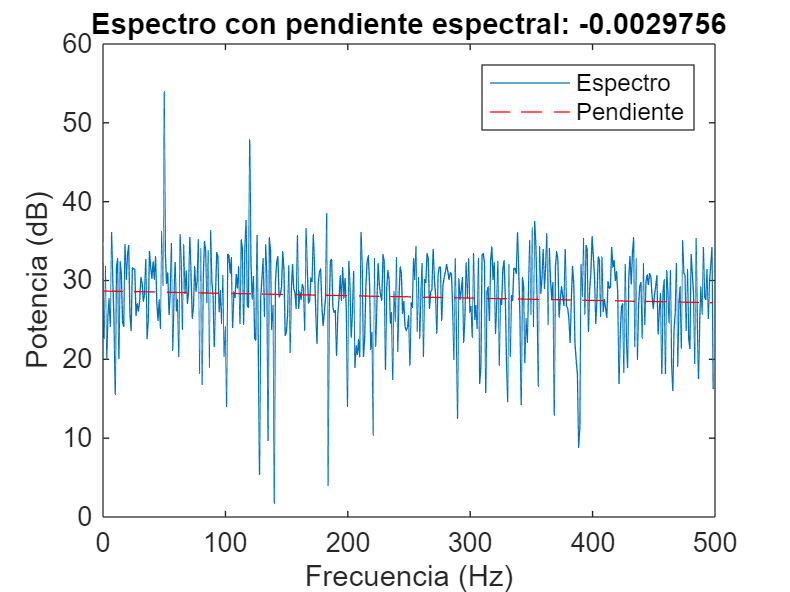

% Calcular pendiente espectral
power_spectrum = X.^2; % Potencia espectral
slope_val = polyfit(f, 10*log10(power_spectrum), 1); % Pendiente

% Visualización de la pendiente espectral
figure;
plot(f, 10*log10(power_spectrum));
hold on;
plot(f, polyval(slope_val, f), 'r--'); % Línea de pendiente
title(['Espectro con pendiente espectral: ', num2str(slope_val(1))]);
xlabel('Frecuencia (Hz)');
ylabel('Potencia (dB)');
legend('Espectro', 'Pendiente');

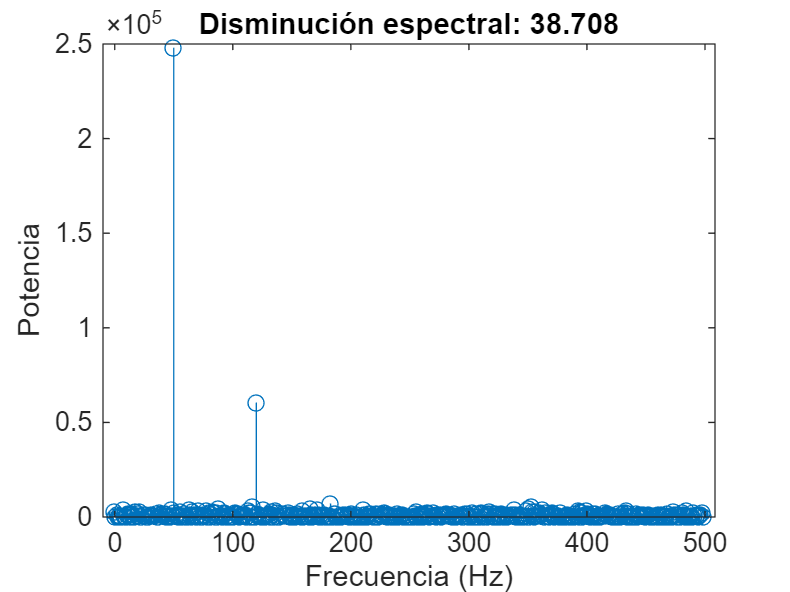

% Calcular disminución espectral
weights = (2:length(power_spectrum)); % Índices para las frecuencias
decrease_val = sum(power_spectrum(2:end) ./ (power_spectrum(1:end-1) .* weights));

% Visualización de la disminución espectral
figure;
stem(f, power_spectrum);
title(['Disminución espectral: ', num2str(decrease_val)]);
xlabel('Frecuencia (Hz)');
ylabel('Potencia');